# ANALISI DEI DATI ACQUISITI DURANTE I TEST "SOLLEVAMENTO A VUOTO"

In questo script si analizzano i dati acquisiti durante i test "sollevamento a vuoto" eseguiti il giorno 05/03/2021 presso SAMAG. Il fine è quello di descrivere il funzionamento delle principali funzioni della libreria e dimostrare l'efficacia del test.

All'inizio tutte le acquisizioni grezze vengono caricate in memoria.

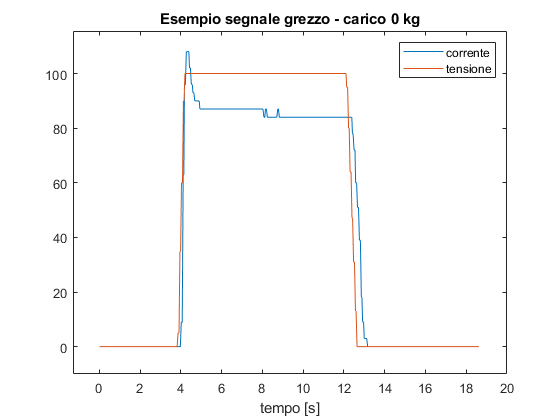

load('Test_SV_05_03_2021.mat')

% Plot di uno dei tanti segnali grezzi acquisiti dall'inverter
% (per mostrare il loro tipico andamento nel tempo)
figure
plot(SV_0kg_8s_2(:,1),SV_0kg_8s_2(:,2))
hold on
plot(SV_57kg_8s_2(:,1),SV_57kg_8s_2(:,3))
title('Esempio segnale grezzo - carico 0 kg')
xlabel('tempo [s]')
legend('corrente','tensione')
axis padded

## Scelta del segnale nominale e ricampionamento di tutti i segnali

Una delle acquisizioni viene scelta come segnale nominale da usare come riferimento di buona salute del mezzo (qui il segnale di uno dei due test eseguiti con 0 kg di carico). Tutti gli altri segnali verranno confrontati con questo per determinare l'indicatore di condizione del mezzo.

Dal momento che il campionamento del segnale nominale scelto potrebbe non essere costante questo viene ricampionato alla sua frequenza di campionamento media.

Analogamente tutti gli altri segnali vengono ricampionati alla stessa frequenza di campionamento del segnale nominale per ottenere segnali confrontabili.

% Scelgo il segnale nominale e lo ricampiono ad una frequenza di campionamento 
% fissa pari alla frequenza di acquisizione media e salvo il risultato in una
% struttura dati
Sn = ricampionaSegnale(SV_0kg_8s_2(:,2), SV_0kg_8s_2(:,1),0);

% Ricampiono gli altri segnali ad una frequenza di campionamento fissa
% uguale a quella usata per il segnale nominale e salvo i risultati in
% strutture dati.
S_0kg = ricampionaSegnale(SV_0kg_8s_2(:,2), SV_0kg_8s_2(:,1),Sn.f); % (copia del segnale nominale)
S_11kg = ricampionaSegnale(SV_11kg_8s_2(:,2), SV_11kg_8s_2(:,1),Sn.f);
S_24kg = ricampionaSegnale(SV_24kg_8s_2(:,2), SV_24kg_8s_2(:,1),Sn.f);
S_37kg = ricampionaSegnale(SV_37kg_8s_2(:,2), SV_37kg_8s_2(:,1),Sn.f);
S_48kg = ricampionaSegnale(SV_48kg_8s_2(:,2), SV_48kg_8s_2(:,1),Sn.f);
S_57kg = ricampionaSegnale(SV_57kg_8s_2(:,2), SV_57kg_8s_2(:,1),Sn.f);

## Elaborazione del segnale nominale

Il segnale nominale ha al suo inizio e alla sua fine delle acquisizioni non significative per il test. Il segnale utile viene quindi identificato e tagliato dal resto.

Dal momento che il segnale nominale scelto è un riferimento costante non cambia i risultati dell'elaborazione vengono salvati per essere riutilizzati immediatamente in altri test senza necessità di ripetere queste operazioni.

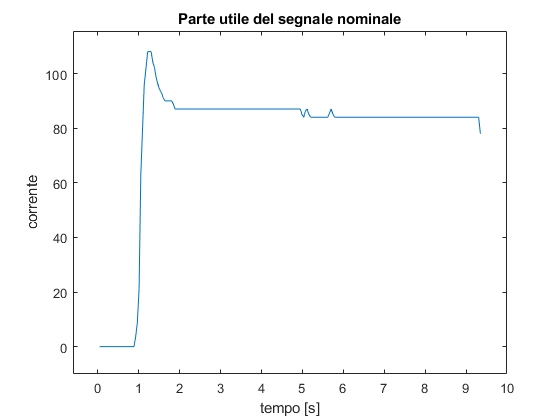

% Parametri per elaborazione del segnale nominale
n_d = 8; % [2,8] ordine del filtro FIR usato per calcolare la derivata prima
inizio_soglia = 0.7; % (0,1] soglia come moltiplicatore per determinare l'inizio del segnale utile
fine_soglia = 0.7; % (0,1] soglia come moltiplicatore per determinare la fine del segnale utile
margine_inizio = 1; % [s] margine di tempo aggiunto all'inizio del segnale utile identificato
margine_fine = -0.5; % [s] margine di tempo aggiunto alla fine del segnale utile identificato

Sn_t = tagliaSegnaleUtile_sv(Sn,n_d,inizio_soglia,fine_soglia,margine_inizio,margine_fine);

% Plot del segnale utile identificato e ritagliato
figure
plotSegnale(Sn_t);
title('Parte utile del segnale nominale')
ylabel('corrente')
axis padded


% Il pratica questo segnale verrà salvato per poter essere riutilizzato
% quando serve senza bisogno di ripetere le elaborazioni
% "save(Sn_t);"

## Elaborazione dei segnali acquisiti

I segnali acquisiti hanno al suo inizio e alla loro fine delle acquisizioni non significative per il test.  La parte utile dei segnali viene quindi identificata e tagliata dal resto.

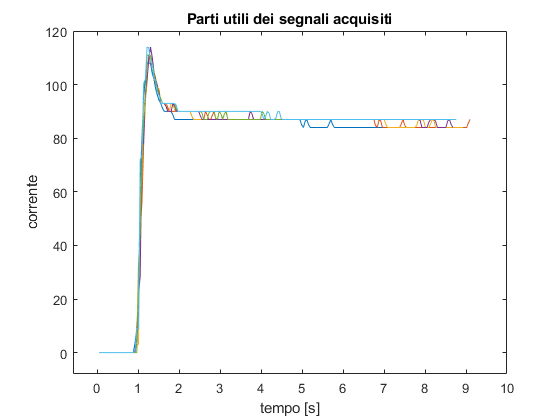

% Parametri per elaborazione dei segnali acquisiti
n_d = 8; % [2,8] ordine del filtro FIR usato per calcolare la derivata prima
inizio_soglia = 0.7; % (0,1] soglia come moltiplicatore per determinare l'inizio del segnale utile
fine_soglia = 0.7; % (0,1] soglia come moltiplicatore per determinare la fine del segnale utile
margine_inizio = 1; % [s] margine di tempo aggiunto all'inizio del segnale utile identificato
margine_fine = -1; % [s] margine di tempo aggiunto alla fine del segnale utile identificato

S_0kg_t = tagliaSegnaleUtile_sv(S_0kg,n_d,inizio_soglia,fine_soglia,margine_inizio,margine_fine);
S_11kg_t = tagliaSegnaleUtile_sv(S_11kg,n_d,inizio_soglia,fine_soglia,margine_inizio,margine_fine);
S_24kg_t = tagliaSegnaleUtile_sv(S_24kg,n_d,inizio_soglia,fine_soglia,margine_inizio,margine_fine);
S_37kg_t = tagliaSegnaleUtile_sv(S_37kg,n_d,inizio_soglia,fine_soglia,margine_inizio,margine_fine);
S_48kg_t = tagliaSegnaleUtile_sv(S_48kg,n_d,inizio_soglia,fine_soglia,margine_inizio,margine_fine);
S_57kg_t = tagliaSegnaleUtile_sv(S_57kg,n_d,inizio_soglia,fine_soglia,margine_inizio,margine_fine);

% Plot dei segnali utili identificati e ritagliati
figure
plotSegnale(S_0kg_t);
hold on
plotSegnale(S_11kg_t);
plotSegnale(S_24kg_t);
plotSegnale(S_37kg_t);
plotSegnale(S_48kg_t);
plotSegnale(S_57kg_t);
title('Parti utili dei segnali acquisiti')
ylabel('corrente')
axis padded

## Calcolo indice "Minimo Errore Quadratico Medio"

Viene calcolato un indicatore di somiglianza tra il segnale nominale e i segnali acquisitoi Tale indicatore determina lo stato di salute del mezzo e la sua idoneità ad essere utilizzato.

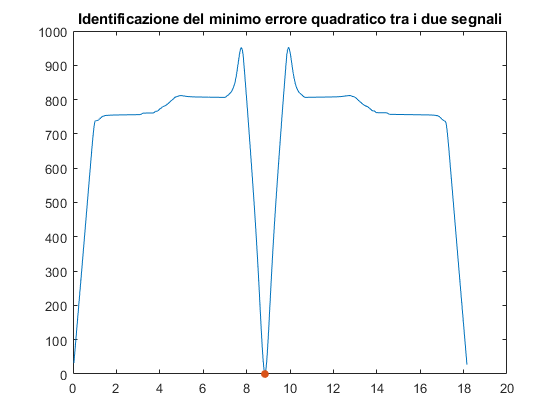

% Calcolo dell'indice di correlaizione tra il segnale nominale e ciascuno dei 
% segnali acquisiti. Minore è l'indice maggiore è la somiglianza tra i due segnali.
ind_0kg = Ind_minErroreQuadraticoMedio_sv(Sn_t,S_0kg_t);

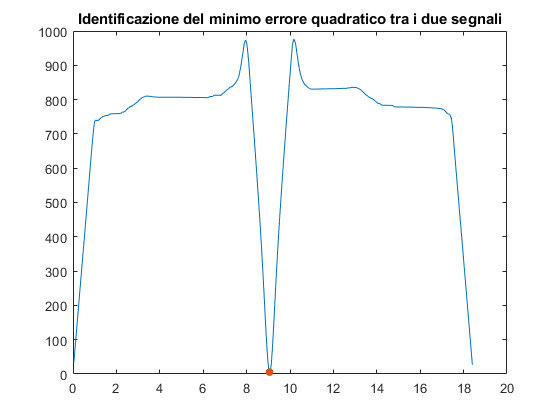

ind_11kg = Ind_minErroreQuadraticoMedio_sv(Sn_t,S_11kg_t);

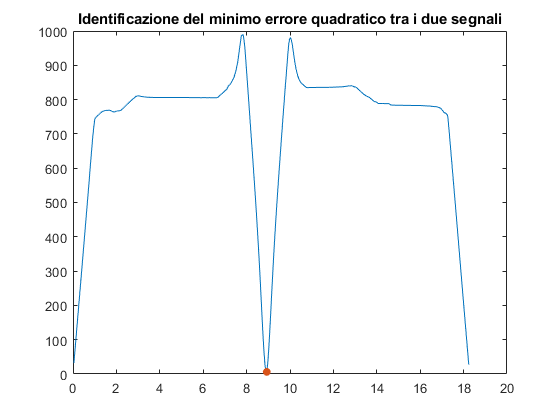

ind_24kg = Ind_minErroreQuadraticoMedio_sv(Sn_t,S_24kg_t);

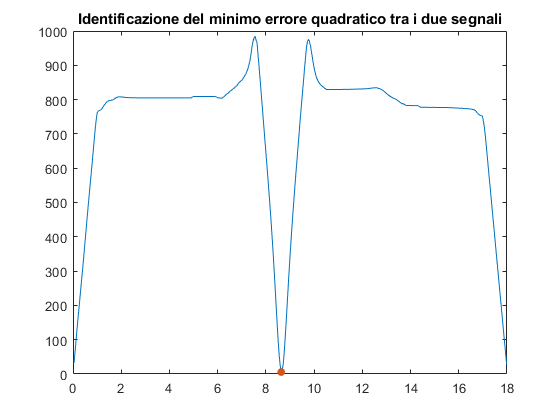

ind_37kg = Ind_minErroreQuadraticoMedio_sv(Sn_t,S_37kg_t);

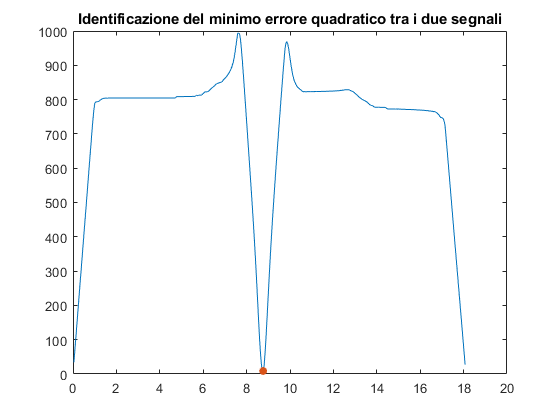

ind_48kg = Ind_minErroreQuadraticoMedio_sv(Sn_t,S_48kg_t);

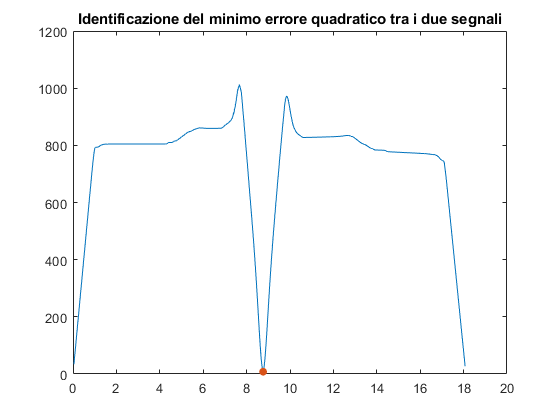

ind_57kg = Ind_minErroreQuadraticoMedio_sv(Sn_t,S_57kg_t);

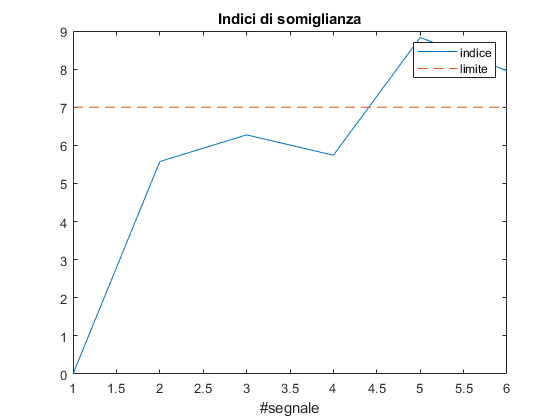


% In base a una soglia si determina se il mezzo su cui è eseguito il test è
% idoneo ad essere utilizzato
ind_lim = 7;

% Plot degli indici di somiglianza calcolati e del limite imposto
figure
Y_plot_temp = [ind_0kg ind_11kg ind_24kg ind_37kg ind_48kg ind_57kg];
plot(Y_plot_temp)
hold on
plot(ones(1,length(Y_plot_temp))*ind_lim,'--')
title('Indici di somiglianza')
xlabel('#segnale')
legend('indice','limite')